# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Newstru\Newstru2\RawData'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 1;
Deci.Proceed            = true;  
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Newstru\Newstru2\ProcessedData'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {9};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {10};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};   
    Deci.DT.Locks      = [14 30 50];
    Deci.DT.Toi        = [-2 3]; 
    
    Deci.DT.Block.Start = {11};
    Deci.DT.Block.End = {12};
    Deci.DT.Block.Markers = [];

## 2. PreProcessing Steps

Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.

## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];  

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =true;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3]; 
Deci.Analysis.DownSample = 500;

#### Time-Frequency Analysis

Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 

Deci.Analysis.Var =false;
Deci.Analysis.Clean = true;

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Plot.Conditions = {[20 31 51] [21 31 51] [23 31 51] [24 31 51] [20 31 52] [21 31 52] [23 31 52] [24 31 52] ...
                            [20 32 51] [21 32 51] [23 32 51] [24 32 51] [20 32 52] [21 32 52] [23 32 52] [24 32 52]};
    Deci.Plot.Var = false;
    Deci.Plot.GA = true;

#### Math

%Deci.Plot.Math.Form = {'[x4+x2]/2','[x7+x5]/2','[x2+x5]/2','[x4+x7]/2' '[x17-x18]' '[x19-x20]'...
%                       '[x2-x4]','[x5-x7]','[x4-x7]','[x2-x5]' '[[x2+x3+x4+x13+x14+x15]/6]' '[[x5+x6+x7+x10+x11+x12]/6]' '[x27-x28]'};   
%Deci.Plot.Math.Type = 0;


#### Conditions

Deci.Plot.Draw = {[1:16]};
Deci.Plot.Title = {'All trials'};
Deci.Plot.Subtitle = {{'G_BTE' 'g_BTE' '0_BTE' 'X_BTE' 'G_WTE' 'g_WTE' '0_WTE' 'X_WTE' ...
                       'N_BTE' 'n_BTE' 'Z_WTE' 'Y_WTE' 'N_WTE' 'n_WTE' 'G_BTE' 'Y_BTE'}};
Deci.Plot.Figures = [true];

#### Time-Frequency

%Deci.Plot.Freq.Foi = [];
Deci.Plot.Freq.Foi = [4 8];
Deci.Plot.Freq.Toi = [0 .8];
Deci.Plot.Freq.Channel = ['Reinhart-All'];
Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxmin';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

Deci.Plot.Freq.Topo =1;
Deci.Plot.Freq.Square =1;

Deci.Plot.Freq.Wires.avg =  'freq';


#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1 2 5 6 9 10 13 14] [3 7 11 15] [4 8 12 16]};
Deci.Plot.Behv.Acc.Subtotal = {[1 2 5 6] [3 7] [4 8]};
Deci.Plot.Behv.Acc.Title = {'Traditional GN' 'OZ' 'XY'};
Deci.Plot.Behv.Acc.Subtitle = {'Percent Choice Opt' 'Percent 0' 'Percent X'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  true;

Deci.Plot.Behv.RT.Draw = {[1 2 5 6] [9 10 13 14] [3 7] [11 15] [4 8] [12 16]};
Deci.Plot.Behv.RT.Title = {'Gg RT' 'Nn RT' '0 RT' 'X RT' 'Z RT' 'Y RT'};
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =false;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = false;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;

## ** 6. Run**

----------------------
Starting DefineTrialor
Found 460 trials for Instru2_EEG_013
Saving Preprocessing Data
Found 474 trials for Instru2_EEG_018
Saving Preprocessing Data
Finished DefineTrial at 5.8066
----------------------
----------------------
Starting PreProcessor for Instru2_EEG_013
Implicit Rereference
Ocular Rereference
Highbandpass Filter
Baseline Correction
Saving Preprocessing Data
Finished PreProcessor at 94.964
----------------------
----------------------
Starting PreProcessor for Instru2_EEG_018
Implicit Rereference
Ocular Rereference
Highbandpass Filter
Baseline Correction
Saving Preprocessing Data
Finished PreProcessor at 95.4737
----------------------
----------------------
Starting Artifactor


searching for artifacts in 62 channels
searching in trial 460 from 460



detected 66 artifacts
the call to "ft_artifact_zvalue" took 90 seconds


searching for artifacts in 4 channels
searching in trial 460 from 460



detected 26 artifacts
the call to "ft_artifact_zvalue" took 13 seconds
detected  66 muscle artifacts
detected  26 eog artifacts
rejected   23 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained    7 trials with artifacts outside critical window
resulting 437 trials
the input is raw data with 62 channels and 460 trials


the call to "ft_redefinetrial" took 10 seconds
the call to "ft_rejectartifact" took 10 seconds
the input is raw data with 62 channels and 437 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 437 trials


showing a summary of the data for all channels and trials


computing metric [--|                                                      ]computing metric [------/                                                  ]computing metric [------------                                             ]computing metric [---------------\                                         ]computing metric [--------------------|                                    ]computing metric [-------------------------/                               ]computing metric [-------------------------------                          ]computing metric [------------------------------------\                    ]computing metric [-----------------------------------------|               ]computing metric [-----------------------------------------------/         ]computing metric [------------------------------------------------------   ]computing metric [--------------------------------------------------------\]


415 trials marked as GOOD, 22 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 59, 68, 127, 141, 147, 217, 218, 219, 243, 258, 305, 318, 346, 347, 362, 366, 367, 386, 390, 391, 395, 401


the call to "ft_rejectvisual" took 66 seconds
the input is raw data with 62 channels and 415 trials


baseline correcting data 
scaling data with 1 over 58.862485
concatenating data...............................................................................................................................................................................................................................................................................................................................................................................................................................
concatenated data matrix size 62x2039807
starting decomposition using runica

Input data size [20,2039807] = 20 channels, 2039807 frames/nAfter PCA dimension reduction,
  finding 20 ICA components using logistic ICA.
Decomposing 5099 frames per ICA weight ((400)^2 = 2039807 weights, Initial learning rate will be 0.001, block size 73.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 

baseline correcting data 
scaling data with 1 over 42.339013
not concatenating data
starting decomposition using predetermined unmixing matrix
not applying the backprojection matrix to the sensor description
the call to "ft_componentanalysis" took 5 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds


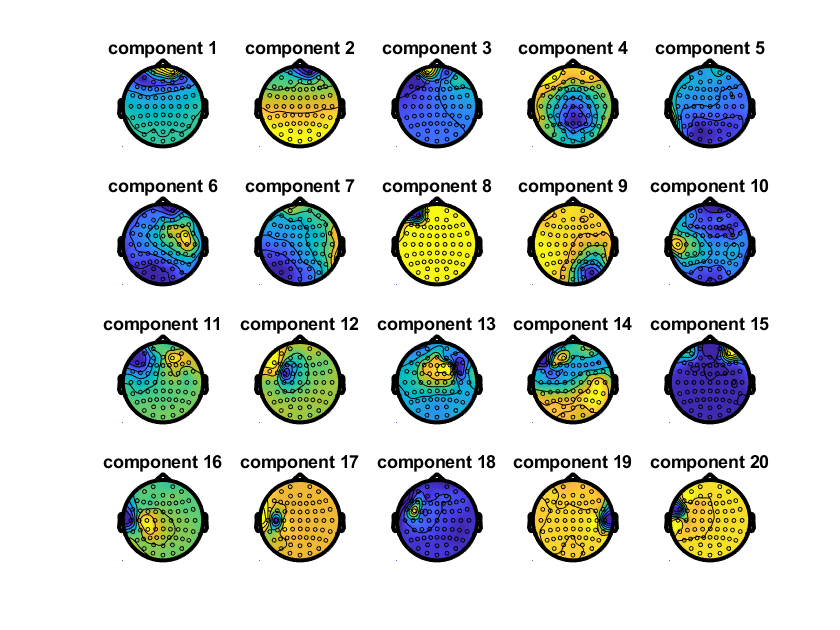

the call to "ft_topoplotIC" took 7 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the input is component data with 20 components and 62 original channels
the input is raw data with 20 channels and 460 trials
detected   0 visual artifacts


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



removing 5 components
keeping 15 components
not applying the backprojection matrix to the sensor description
the call to "ft_rejectcomponent" took 1 seconds


detected 62 artifacts
the call to "ft_artifact_zvalue" took 87 seconds


detected 10 artifacts
the call to "ft_artifact_zvalue" took 13 seconds
detected  62 muscle artifacts
detected  10 eog artifacts
rejected   16 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained    4 trials with artifacts outside critical window
resulting 444 trials
the input is raw data with 62 channels and 460 trials


the call to "ft_redefinetrial" took 10 seconds
the call to "ft_rejectartifact" took 10 seconds
the input is raw data with 62 channels and 444 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 444 trials


showing a summary of the data for all channels and trials


computing metric [-----|                                                   ]computing metric [---------/                                               ]computing metric [---------------                                          ]computing metric [-------------------\                                     ]computing metric [------------------------|                                ]computing metric [------------------------------/                          ]computing metric [------------------------------------                     ]computing metric [-----------------------------------------\               ]computing metric [-----------------------------------------------|         ]computing metric [----------------------------------------------------/    ]computing metric [---------------------------------------------------------]


432 trials marked as GOOD, 12 trials marked as BAD
4 channels marked as GOOD, 58 channels marked as BAD
no channels were removed from the data
the following trials were removed: 130, 160, 221, 222, 324, 328, 343, 369, 373, 397, 408, 432


the call to "ft_rejectvisual" took 42 seconds


the input is raw data with 62 channels and 432 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 432 trials


showing a summary of the data for all channels and trials


computing metric [-----|                                                   ]computing metric [----------/                                              ]computing metric [----------------                                         ]computing metric [--------------------\                                    ]computing metric [--------------------------|                              ]computing metric [-------------------------------/                         ]computing metric [--------------------------------------                   ]computing metric [------------------------------------------\              ]computing metric [------------------------------------------------|        ]computing metric [-----------------------------------------------------/   ]computing metric [---------------------------------------------------------]


424 trials marked as GOOD, 8 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 219, 258, 260, 340, 363, 364, 405, 420


the call to "ft_rejectvisual" took 150 seconds


searching for artifacts in 62 channels
searching in trial 474 from 474



detected 109 artifacts
the call to "ft_artifact_zvalue" took 93 seconds


searching for artifacts in 4 channels
searching in trial 474 from 474



detected 21 artifacts
the call to "ft_artifact_zvalue" took 14 seconds
detected 109 muscle artifacts
detected  21 eog artifacts
rejected   67 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   27 trials with artifacts outside critical window
resulting 407 trials
the input is raw data with 62 channels and 474 trials


the call to "ft_redefinetrial" took 9 seconds
the call to "ft_rejectartifact" took 10 seconds
the input is raw data with 62 channels and 407 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 407 trials


showing a summary of the data for all channels and trials


computing metric [----|                                                    ]computing metric [---------/                                               ]computing metric [----------------                                         ]computing metric [--------------------\                                    ]computing metric [-------------------------|                               ]computing metric [------------------------------/                          ]computing metric [-------------------------------------                    ]computing metric [-----------------------------------------\               ]computing metric [-----------------------------------------------|         ]computing metric [----------------------------------------------------/    ]computing metric [---------------------------------------------------------]


386 trials marked as GOOD, 21 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 75, 77, 78, 79, 97, 107, 120, 146, 161, 163, 171, 174, 178, 190, 216, 225, 230, 232, 233, 299, 349


the call to "ft_rejectvisual" took 71 seconds
the input is raw data with 62 channels and 386 trials


baseline correcting data 
scaling data with 1 over 95.195726
concatenating data..................................................................................................................................................................................................................................................................................................................................................................................................
concatenated data matrix size 62x1895607
starting decomposition using runica

Input data size [20,1895607] = 20 channels, 1895607 frames/nAfter PCA dimension reduction,
  finding 20 ICA components using logistic ICA.
Decomposing 4739 frames per ICA weight ((400)^2 = 1895607 weights, Initial learning rate will be 0.001, block size 73.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bi

baseline correcting data 
scaling data with 1 over 76.490769
not concatenating data
starting decomposition using predetermined unmixing matrix
not applying the backprojection matrix to the sensor description
the call to "ft_componentanalysis" took 5 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds


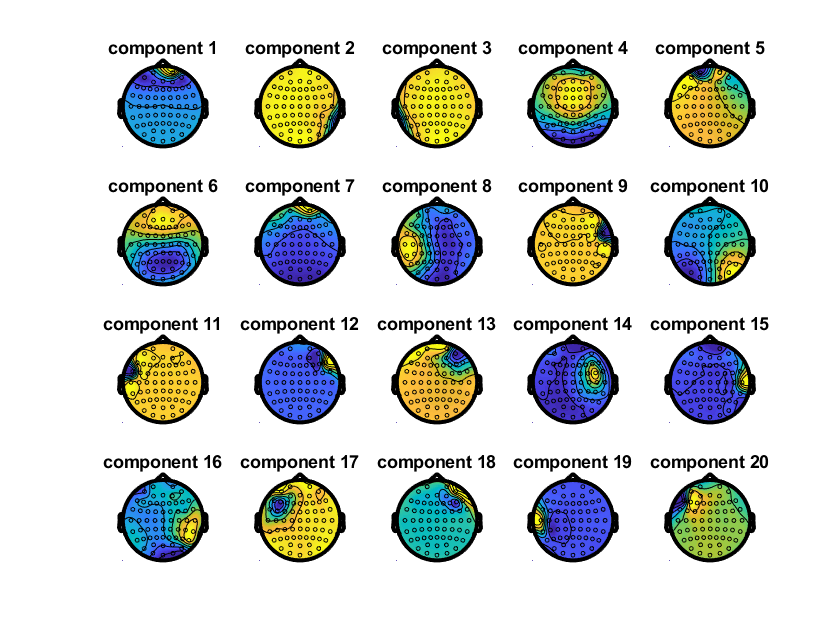

the call to "ft_topoplotIC" took 5 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the input is component data with 20 components and 62 original channels
the input is raw data with 20 channels and 474 trials
detected   0 visual artifacts


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



removing 4 components
keeping 16 components
not applying the backprojection matrix to the sensor description
the call to "ft_rejectcomponent" took 1 seconds


detected 118 artifacts
the call to "ft_artifact_zvalue" took 91 seconds


detected 63 artifacts
the call to "ft_artifact_zvalue" took 13 seconds
detected 118 muscle artifacts
detected  63 eog artifacts
rejected   87 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   32 trials with artifacts outside critical window
resulting 387 trials
the input is raw data with 62 channels and 474 trials


the call to "ft_redefinetrial" took 9 seconds
the call to "ft_rejectartifact" took 9 seconds
the input is raw data with 62 channels and 387 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 387 trials


showing a summary of the data for all channels and trials


computing metric [-----|                                                   ]computing metric [----------/                                              ]computing metric [-----------------                                        ]computing metric [----------------------\                                  ]computing metric [---------------------------|                             ]computing metric [---------------------------------/                       ]computing metric [----------------------------------------                 ]computing metric [---------------------------------------------\           ]computing metric [---------------------------------------------------|     ]computing metric [--------------------------------------------------------/]


369 trials marked as GOOD, 18 trials marked as BAD
4 channels marked as GOOD, 58 channels marked as BAD
no channels were removed from the data
the following trials were removed: 71, 74, 75, 103, 119, 125, 140, 155, 163, 177, 183, 185, 186, 219, 225, 229, 248, 251


the call to "ft_rejectvisual" took 80 seconds


the input is raw data with 62 channels and 369 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 369 trials


showing a summary of the data for all channels and trials


computing metric [-----|                                                   ]computing metric [-----------/                                             ]computing metric [------------------                                       ]computing metric [----------------------\                                  ]computing metric [----------------------------|                            ]computing metric [----------------------------------/                      ]computing metric [------------------------------------------               ]computing metric [-----------------------------------------------\         ]computing metric [-----------------------------------------------------|   ]computing metric [--------------------------------------------------------/]


359 trials marked as GOOD, 10 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 27, 30, 72, 73, 138, 146, 158, 168, 196, 312


the call to "ft_rejectvisual" took 35 seconds


Finished Artifactor at 1634.0747
----------------------
the input is raw data with 62 channels and 424 trials


using electrodes specified in the configuration
computing SCD for trial 424 of 424



output surface laplacian is in uV/m^2
the call to "ft_scalpcurrentdensity" took 39 seconds
the input is raw data with 60 channels and 424 trials
resampling data
resampling data in trial 424 from 424

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 15 seconds
the input is raw data with 60 channels and 424 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 60 channels and 424 trials


processing trials
trial 424, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 213 seconds


preprocessing
preprocessing trial 424 from 424

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 60 channels
searching in trial 424 from 424

detected 5 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
preprocessing
preprocessing trial 424 from 424

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 20 channels
searching in trial 424 from 424

detected 0 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
detected   5 muscle artifacts
detected   0 eog artifacts
rejected    4 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 420 trials
the input is raw data with 20 channels and 424 trials
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_rejectartifact" took 0 seconds


Elapsed time is 222.538148 seconds.
the input is raw data with 60 channels and 424 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 60 channels and 424 trials


processing trials
trial 424, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 212 seconds


preprocessing
preprocessing trial 424 from 424

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 60 channels
searching in trial 424 from 424

detected 3 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
preprocessing
preprocessing trial 424 from 424

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 20 channels
searching in trial 424 from 424

detected 0 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
detected   3 muscle artifacts
detected   0 eog artifacts
rejected    3 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 421 trials
the input is raw data with 20 channels and 424 trials
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_rejectartifact" took 0 seconds


Elapsed time is 228.972721 seconds.
the input is raw data with 60 channels and 424 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 60 channels and 424 trials


processing trials
trial 424, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 212 seconds


preprocessing
preprocessing trial 424 from 424

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 60 channels
searching in trial 424 from 424

detected 10 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
preprocessing
preprocessing trial 424 from 424

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 20 channels
searching in trial 424 from 424

detected 0 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
detected  10 muscle artifacts
detected   0 eog artifacts
rejected    8 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 416 trials
the input is raw data with 20 channels and 424 trials
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_rejectartifact" took 0 seconds


Elapsed time is 224.900755 seconds.
the input is raw data with 62 channels and 359 trials


using electrodes specified in the configuration
computing SCD for trial 359 of 359



output surface laplacian is in uV/m^2
the call to "ft_scalpcurrentdensity" took 31 seconds
the input is raw data with 60 channels and 359 trials
resampling data
resampling data in trial 359 from 359

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 11 seconds
the input is raw data with 60 channels and 359 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 60 channels and 359 trials


processing trials
trial 359, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 178 seconds


preprocessing
preprocessing trial 359 from 359

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 60 channels
searching in trial 359 from 359

detected 14 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
preprocessing
preprocessing trial 359 from 359

the call to "ft_preprocessing" took 0 seconds
searching for artifacts in 20 channels
searching in trial 359 from 359

detected 0 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
detected  14 muscle artifacts
detected   0 eog artifacts
rejected   13 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 346 trials
the input is raw data with 20 channels and 359 trials
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_rejectartifact" took 0 seconds


Elapsed time is 190.939550 seconds.
the input is raw data with 60 channels and 359 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 60 channels and 359 trials


processing trials
trial 359, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 177 seconds


preprocessing
preprocessing trial 359 from 359

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 60 channels
searching in trial 359 from 359

detected 5 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
preprocessing
preprocessing trial 359 from 359

the call to "ft_preprocessing" took 0 seconds
searching for artifacts in 20 channels
searching in trial 359 from 359

detected 0 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
detected   5 muscle artifacts
detected   0 eog artifacts
rejected    5 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 354 trials
the input is raw data with 20 channels and 359 trials
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_rejectartifact" took 0 seconds


Elapsed time is 199.040447 seconds.
the input is raw data with 60 channels and 359 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 60 channels and 359 trials


processing trials
trial 359, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 175 seconds


preprocessing
preprocessing trial 359 from 359

the call to "ft_preprocessing" took 1 seconds
searching for artifacts in 60 channels
searching in trial 359 from 359

detected 17 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
preprocessing
preprocessing trial 359 from 359

the call to "ft_preprocessing" took 0 seconds
searching for artifacts in 20 channels
searching in trial 359 from 359

detected 1 artifacts
the call to "ft_artifact_abszvalue" took 1 seconds
detected  17 muscle artifacts
detected   1 eog artifacts
rejected   17 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
resulting 342 trials
the input is raw data with 20 channels and 359 trials
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_rejectartifact" took 0 seconds


Elapsed time is 188.543462 seconds.
Channel AF3 of 60
Channel AF4 of 60
Channel AF7 of 60
Channel AF8 of 60
Channel AFz of 60
Channel C1 of 60
Channel C2 of 60
Channel C3 of 60
Channel C4 of 60
Channel C5 of 60
Channel C6 of 60
Channel CP1 of 60
Channel CP2 of 60
Channel CP3 of 60
Channel CP4 of 60
Channel CP5 of 60
Channel CP6 of 60
Channel CPz of 60
Channel Cz of 60
Channel F1 of 60
Channel F2 of 60
Channel F3 of 60
Channel F4 of 60
Channel F5 of 60
Channel F6 of 60
Channel F7 of 60
Channel F8 of 60
Channel FC1 of 60
Channel FC2 of 60
Channel FC3 of 60
Channel FC4 of 60
Channel FC5 of 60
Channel FC6 of 60
Channel FCz of 60
Channel FT7 of 60
Channel FT8 of 60
Channel Fz of 60
Channel O1 of 60
Channel O2 of 60
Channel Oz of 60
Channel P1 of 60
Channel P2 of 60
Channel P3 of 60
Channel P4 of 60
Channel P5 of 60
Channel P6 of 60
Channel P7 of 60
Channel P8 of 60
Channel PO3 of 60
Channel PO4 of 60
Channel PO7 of 60
Channel PO8 of 60
Channel POz of 60
Channel Pz of 60
Channel T7 of 60
Cha

the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 2 subjects


the call to "ft_freqgrandaverage" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 se

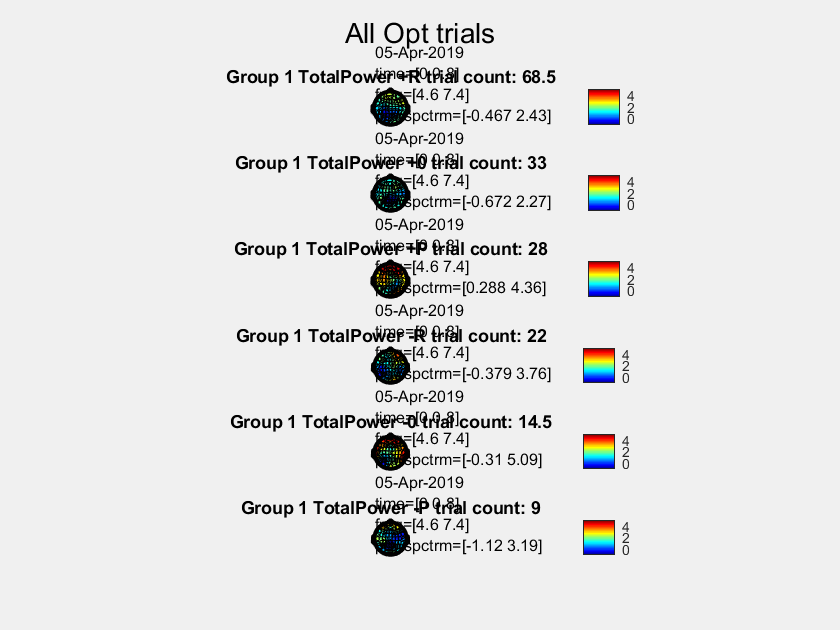

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


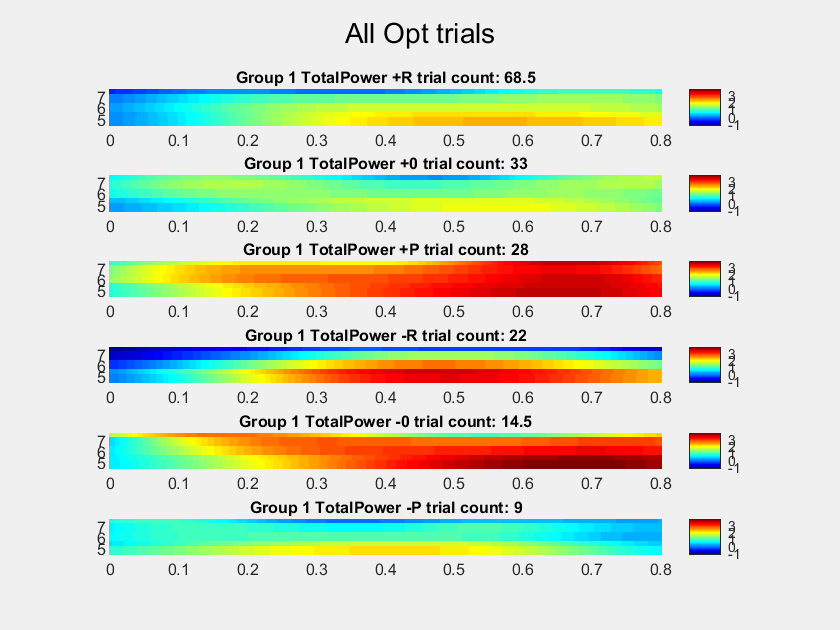

the call to "ft_singleplotTFR" took 0 seconds


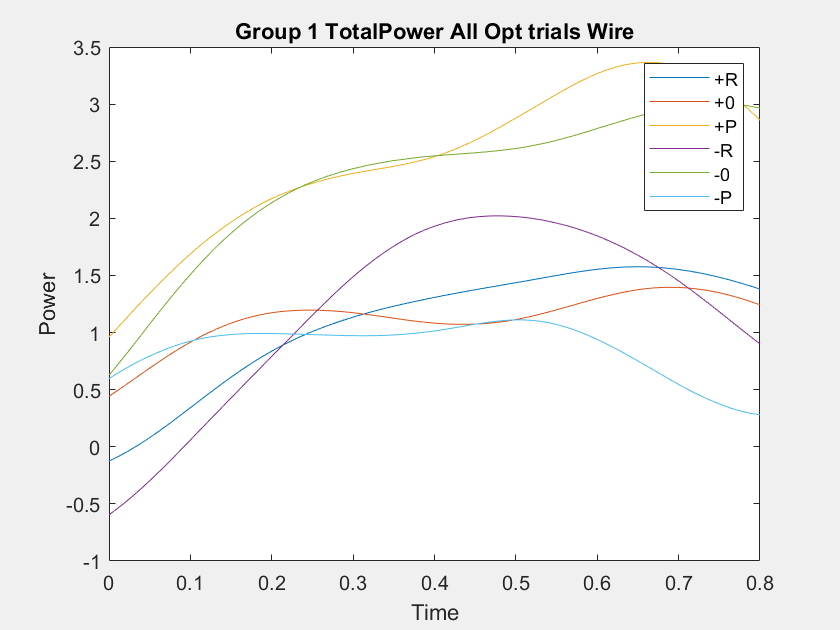

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


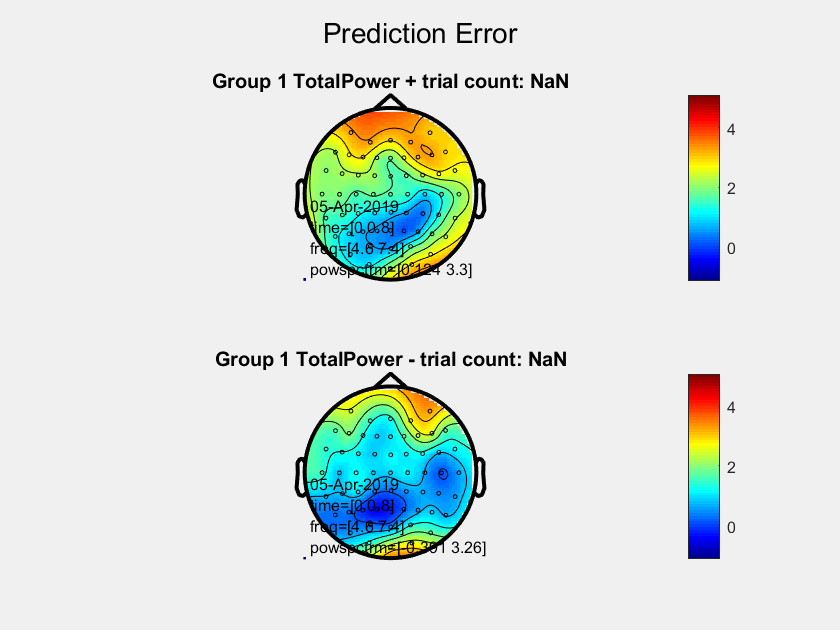

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


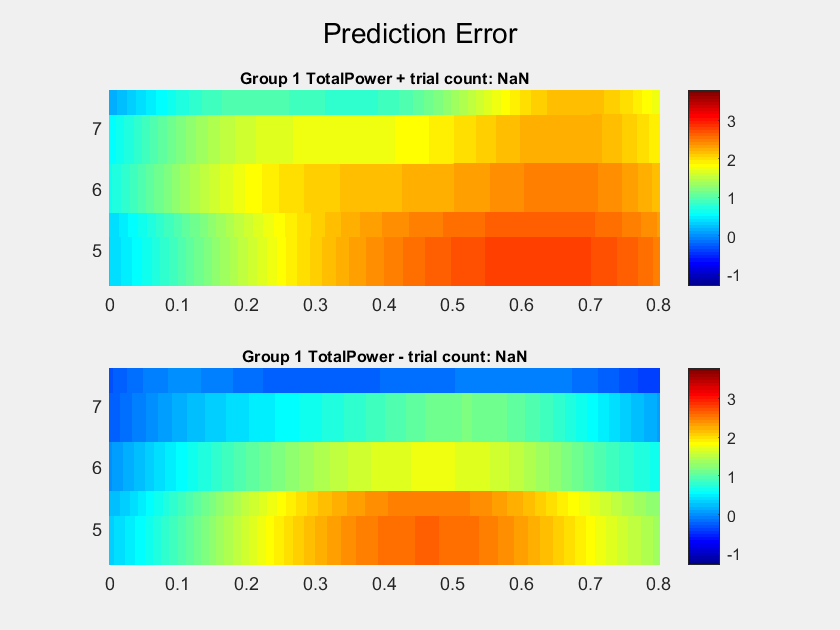

the call to "ft_singleplotTFR" took 0 seconds


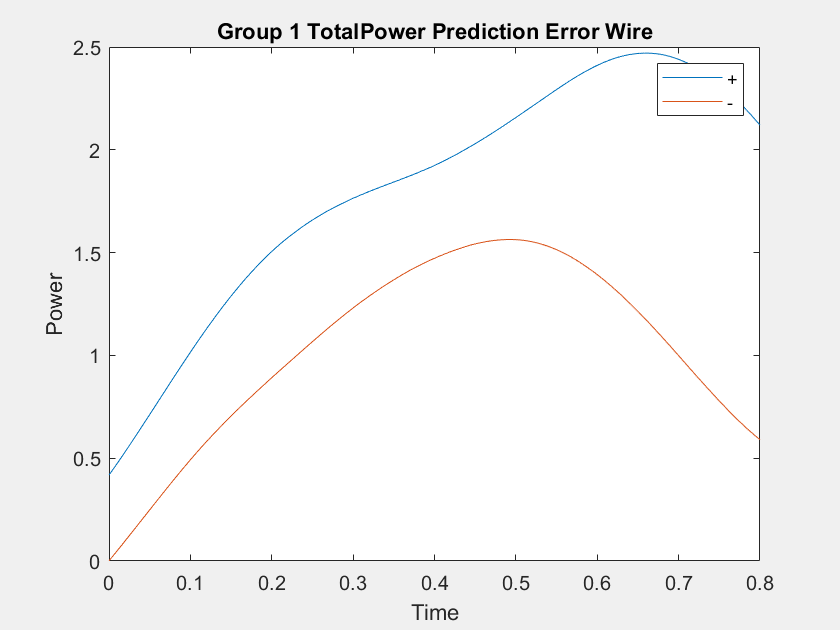

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


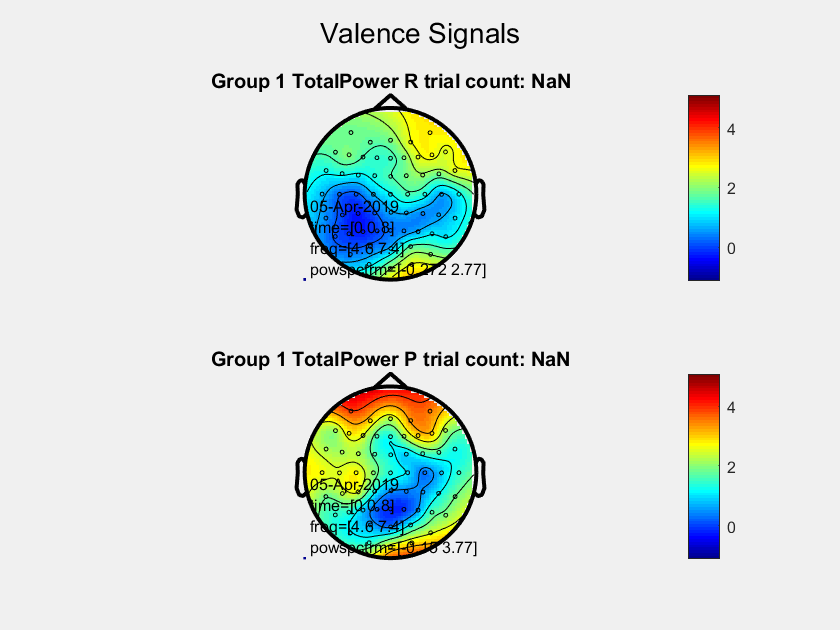

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


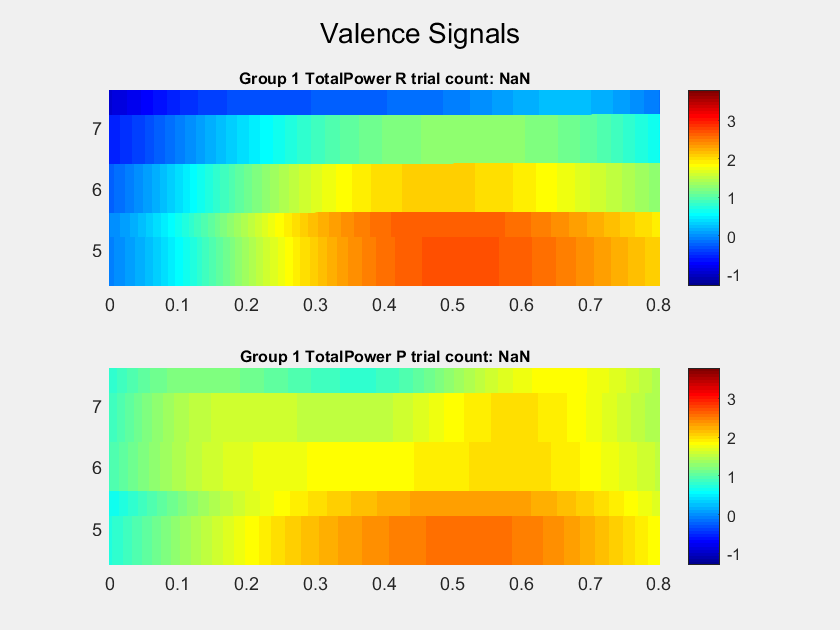

the call to "ft_singleplotTFR" took 0 seconds


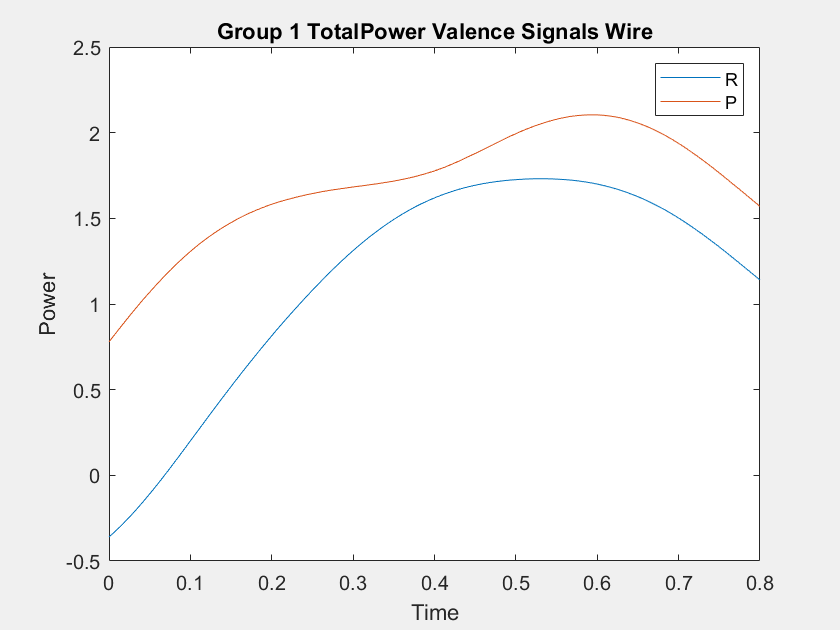

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds



Deci_Backend(Deci);